[TBS, selected_RB, selected_MCS] = selectTBSForFiveUsers_simple(SINR1, SINR2, SINR3, SINR4, SINR5)

TBS = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


selected_RB = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


selected_MCS = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


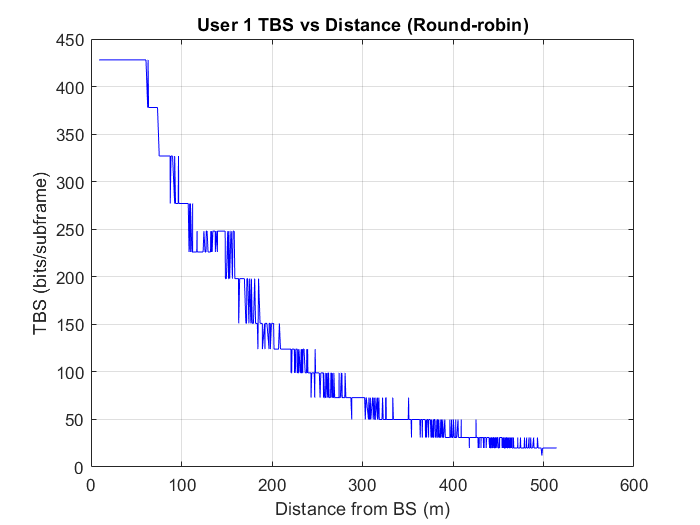


figure; plot(ds, TBS{1}(idx), 'b-'); grid on
xlabel('Distance from BS (m)'); ylabel('TBS (bits/subframe)');
title('User 1 TBS vs Distance (Round-robin)');

function [TBS, selected_RB, selected_MCS] = selectTBSForFiveUsers_simple(SINR1,SINR2,SINR3,SINR4,SINR5)
% Single-function, vectorized SINR -> {TBS, RB, MCS} for 5 users (cell arrays).
% Usage:
%   [TBS,RB,MCS] = selectTBSForFiveUsers_simple(S1,S2,S3,S4,S5);
%   [TBS,RB,MCS] = selectTBSForFiveUsers_simple(S1,S2,S3,S4,S5, 10);

   RB_per_subframe = 1;

    % ---- System assumptions (edit if needed) ----
    RE_per_RB = 84;  % usable RE per RB per subframe (approx)
    % SINR(dB) thresholds for CQI (0..15); use edges for discretize
    edges = [-Inf, -25, -21, -17, -13, -9, -5, -2, 1, 4, 7, 10, 14, 18, 22, 26, Inf];
    % MCS 0..14 -> modulation order and code rate (quick practical model)
    modOrder = [2 2 2 2 2 2 2  4 4 4  6 6 6 6 6];  % QPSK/16QAM/64QAM
    codeRate = [0.076 0.12 0.19 0.30 0.44 0.59 0.74, 0.45 0.59 0.74, 0.45 0.55 0.65 0.75 0.85];

    % ---- Pack inputs to loop once, return as cells ----
    SINR_all = {SINR1, SINR2, SINR3, SINR4, SINR5};
    TBS = cell(1,5); selected_RB = cell(1,5); selected_MCS = cell(1,5);

    for u = 1:5
        s = SINR_all{u}(:);                 % column vector
        n = numel(s);
        RB = RB_per_subframe * ones(n,1);   % default RB allocation

        % SINR -> CQI via binning; bin 1 => CQI 0, ..., bin 16 => CQI 15
        bins = discretize(s, edges);        % 1..16
        cqi  = bins - 1;                    % 0..15

        % CQI -> MCS (0..14); CQI==0 => outage (no data)
        m = max(0, min(14, cqi - 1));       % 0..14
        outage = (cqi == 0);

        % Bits per RB per subframe for valid MCS
        m_idx = m + 1;                      % 1..15
        bprb = RE_per_RB .* modOrder(m_idx)'.* codeRate(m_idx)'; % vectorized

        % Apply outage rules
        RB(outage) = 0;
        MCS = m; MCS(outage) = -1;
        bits = floor(RB .* bprb);
        bits(outage) = 0;

        % Save to cells
        TBS{u}         = bits;
        selected_RB{u} = RB;
        selected_MCS{u}= MCS;
    end
end
